# Test Case - Motor Drive Unit

mdl = "MotorDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorDriveUnit_Component_harness_params

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle speed", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle torque", Before="-10");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", Time="400");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", After="0");

simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Before="150");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Time="300");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", After="-50");

% Initial conditions

simIn = setVariable(simIn, "initial.loadInertiaSpd_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "600");

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

## Visualize Simulation Result

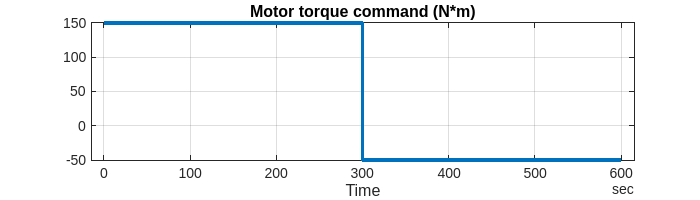

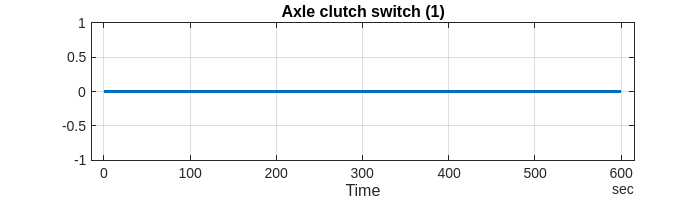

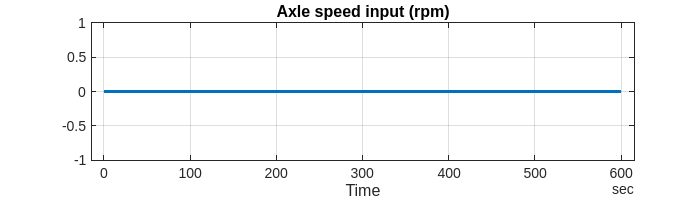

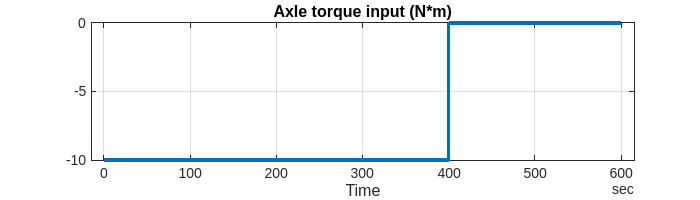

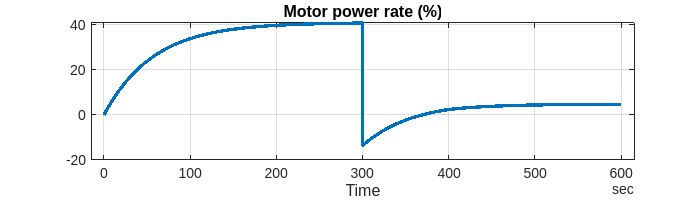

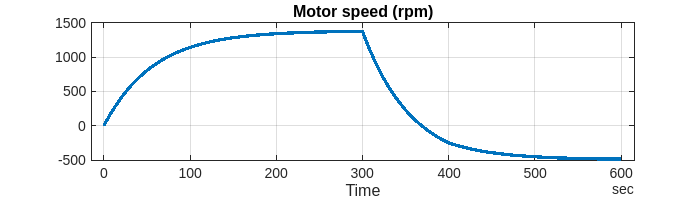

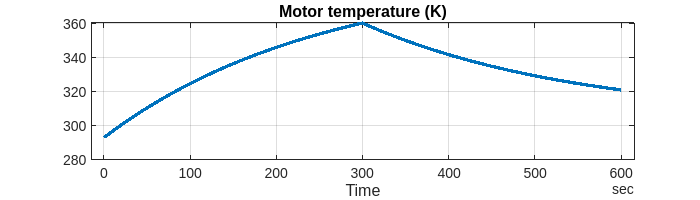

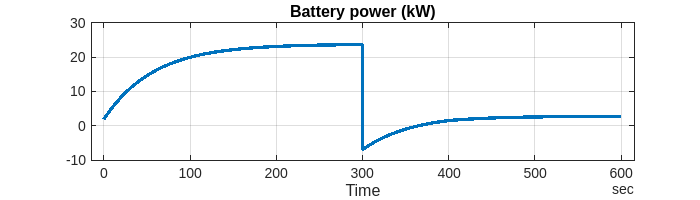

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "Motor torque command",...
  "Axle clutch switch", ...
  "Axle speed input", ...
  "Axle torque input", ...
  "Motor power rate", ...
  "Motor speed", ...
  "Motor temperature", ...
  "Battery power", ...
  "Battery current", ...
  "Battery voltage", ...
  "Battery SOC" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 200;
end

*Copyright 2021-2022 The Mathworks, Inc.*